# Optimization - with space stops

clc;
clear;
close all;

[param, weather, route, driver] = loadData();

effLoss = load("inefficiency.mat").effLoss;
tempCF = load("temperatureCF.mat").tempCF;
velSafe = load("optimalMeanVelocity.mat").velMeanOpt_unitedStops;

cd("C:\Users\giaco\Git_Repositories\Bachelor_Arbeit\Codes\Optimization");

interestDay = datetime(2020,10,20);
enhanceFactor = 1.8;
raceDays = 5;
plotIsRequested = false;
weatherSim = weatherSimFullRace(interestDay, enhanceFactor, raceDays, plotIsRequested);

Colours for plots

colour = struct();
colour.loss = 'r';
colour.solar = 'g';
colour.battery = 'magenta';

Cumulative solar energy

EcumSolar = cumtrapz(weatherSim.irradiance.GtotalSec) * param.pv.area * param.pv.eff * tempCF * param.pv.loss.total; %J

Battery initial energy and safe to spend energy

SoCmin = 0.1;
Ebatmax = param.battery.Emax; %J
EbatSafe = Ebatmax * (1 - SoCmin); %J

## Cut only driving time

horizon_8_17 = logical(weatherSim.irradiance.driving_8_17_Sec); %conversion to logical
time_8_17 = weatherSim.irradiance.timeSec(horizon_8_17);
Gtotal_8_17 = weatherSim.irradiance.GtotalSec(horizon_8_17);

timeLen_8_17 = length(time_8_17);
timeSec_8_17 = linspace(1, timeLen_8_17, timeLen_8_17)'; %CHECK SHIFT BY ONE OF NIGHTS STOP FROM THE SECOND ONE

[timeSec_driving, controlStopBeginSec, finishSec, horizon_driving] = timeVecCreatorForPlots(velSafe, timeSec_8_17);

Space2time: correction of night stops to plot

% CHECK SHIFT BY ONE BETWEEN SEC AND HOUR, MAYBE IS THE FUNCTION TIMEVEC
nightStopHour_17 = (7 : 9 : 9*(raceDays))'; %h
nightStopSec_17 = seconds(hours(nightStopHour_17)); %s

timeBeginIncNextStop = controlStopBeginSec + seconds(minutes(30)) * (0 : length(controlStopBeginSec)-1)';
timeBeginIncNextStopHour = timeBeginIncNextStop / 3600;
timeEndIncNextStopHour = timeBeginIncNextStopHour + hours(minutes(30));
timeBeginStopHour = controlStopBeginSec / 3600;

% timeStopSec_17_cut = zeros(length(timeStopHour_17), 1);
% for i = 1:length(timeStopHour_17)
%     horizonSpaceStops = timeIncNextStop < timeStopSec_17(i); %DANGER WHEN EQUAL?
%     numStops = sum(horizonSpaceStops);
%     timeStopSec_17_cut(i) = timeStopSec_17(i) - numStops * seconds(minutes(30));
% end % for

timeStopHour_17_cut = nightStopHour_17;
idx = 1;
for j = 1:length(timeBeginStopHour)
    if timeStopHour_17_cut(idx) > timeBeginStopHour(j)
        timeStopHour_17_cut(idx) = timeStopHour_17_cut(idx) - hours(minutes(30));
    else
        idx = idx + 1;
        timeStopHour_17_cut(idx) = timeStopHour_17_cut(idx) - j * hours(minutes(30));
    end % if
end % for
% timeStopHour_17_cut(end) = timeStopHour_17_cut(end) - j * hours(minutes(30)); %correct last entry

timeStopSec_17_cut = seconds(hours(timeStopHour_17_cut));

%overlap night/spaceStop correction
overlapNights = false(size(nightStopHour_17));
overlapSpaceStops = false(driver.numSpaceStops, 1);
for i = 1:length(nightStopHour_17)
    overlapIsDetected = timeBeginIncNextStopHour < nightStopHour_17(i) & nightStopHour_17(i) < timeEndIncNextStopHour; %DANGER WHEN EQUAL? ONE SHOULD BE =

    overlapSpaceStops = overlapSpaceStops | overlapIsDetected;
    overlapNights(i) = overlapNights(i) | boolean(sum(overlapIsDetected));
end % for
timeStopSec_17_cut(overlapNights == 1) = controlStopBeginSec(overlapSpaceStops == 1);

Cumulative energy

EcumSolar_8_17 = EcumSolar(horizon_8_17);
EcumSolar_driving = EcumSolar_8_17(horizon_driving);

EbudgetTot_8_17 = EcumSolar_8_17 + EbatSafe;
EbudgetTot_driving = EcumSolar_driving + EbatSafe;

Energy loss

Faero_8_17 = param.constants.aero * (driver.finishLocDist ./ timeSec_8_17).^2; %N
Faero_driving = param.constants.aero * (driver.finishLocDist ./ timeSec_driving).^2; %N
Froll = param.constants.roll; %N

Eloss_8_17 = driver.finishLocDist / effLoss * (Froll + Faero_8_17);
Eloss_driving = driver.finishLocDist / effLoss * (Froll + Faero_driving);

#### Find optimal point

[timeOpt_8_17, velMeanOpt_8_17] = optimalTimeVelocityEstimator(Eloss_8_17, EbudgetTot_8_17);

Optimal driving time: 31.07 h 
Optimal velocity: 97.42 km/h

[timeOpt_driving, velMeanOpt_driving] = optimalTimeVelocityEstimator(Eloss_driving, EbudgetTot_driving);

Optimal driving time: 29.50 h 
Optimal velocity: 102.61 km/h

### Plot

Check

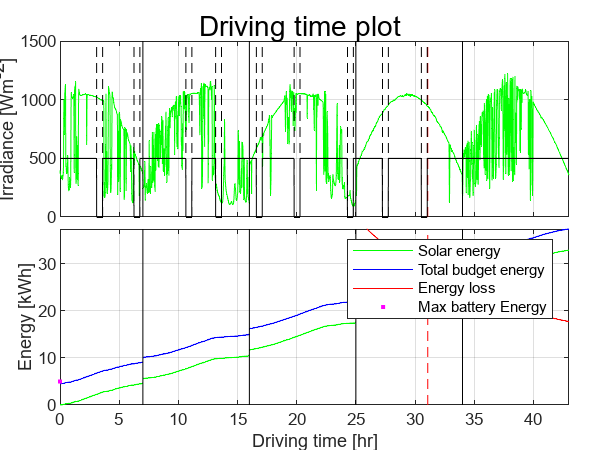

title = 'Driving time plot';
synchronizeXAxes = true;
xaxisTime = timeSec_8_17 / 3600;
yline17 = (7 : 9 : 9*(raceDays-1))';
xlimVecTime = [0, xaxisTime(end)];
ylimVecTime = [0, J2kWh(EcumSolar_8_17(end)+EbatSafe)];
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxisTime, Gtotal_8_17,'-','Color',colour.solar);
builder.addLines('vertical', yline17, 'k');
builder.addLines('vertical', timeOpt_8_17 / 3600, 'r--');
builder.addPlot(xaxisTime, horizon_driving * 500, 'k');
builder.addLines('vertical', timeBeginIncNextStopHour, 'k--');
builder.addLines('vertical', timeEndIncNextStopHour, 'k--');
builder.setYlabel("Irradiance [Wm^{-2}]");
builder.setXlim(xlimVecTime)

builder.startNewSubplot();
builder.addPlot(xaxisTime, J2kWh(EcumSolar_8_17),'-','Color',colour.solar);
builder.addPlot(xaxisTime, J2kWh(EbudgetTot_8_17),'-','Color','b');
builder.addPlot(xaxisTime, J2kWh(Eloss_8_17),'-','Color',colour.loss);
builder.addPlot(0, J2kWh(Ebatmax),'.','Color',colour.battery);
builder.addPlot(timeOpt_8_17 / 3600, J2kWh(Eloss_8_17(timeOpt_8_17)), 'r.', 'MarkerSize', 20)
builder.addLines('vertical', yline17, 'k');
builder.addLines('vertical', timeOpt_8_17 / 3600, 'r--');
builder.setYlabel("Energy [kWh]")
builder.setLegend("Solar energy","Total budget energy","Energy loss","Max battery Energy")
builder.setXlim(xlimVecTime)
builder.setYlim(ylimVecTime)

builder.setXlabel("Driving time [hr]");
builder.drawNow()

#### Energy, irradiance vs driving time

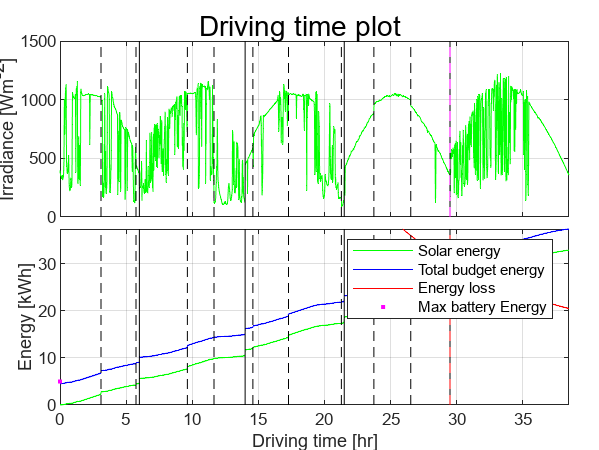

title = 'Driving time plot';
synchronizeXAxes = true;
xaxisTime = timeSec_driving / 3600;
xlimVecTime = [0, xaxisTime(end)];
ylimVecTime = [0, J2kWh(EcumSolar_driving(end)+EbatSafe)];
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxisTime, Gtotal_8_17(horizon_driving),'-','Color',colour.solar);
builder.addLines('vertical', timeStopSec_17_cut / 3600, 'k');
builder.addLines('vertical', timeOpt_driving / 3600, 'r--');
builder.addLines('vertical', controlStopBeginSec / 3600, 'k--');
builder.addLines('vertical', finishSec / 3600, 'magenta--');
builder.setYlabel("Irradiance [Wm^{-2}]");
builder.setXlim(xlimVecTime)

builder.startNewSubplot();
builder.addPlot(xaxisTime, J2kWh(EcumSolar_driving),'-','Color',colour.solar);
builder.addPlot(xaxisTime, J2kWh(EbudgetTot_driving),'-','Color','b');
builder.addPlot(xaxisTime, J2kWh(Eloss_driving),'-','Color',colour.loss);
builder.addPlot(0, J2kWh(Ebatmax),'.','Color',colour.battery);
builder.addPlot(timeOpt_driving / 3600, J2kWh(Eloss_driving(timeOpt_driving)), 'r.', 'MarkerSize', 20)
builder.addLines('vertical', timeStopSec_17_cut / 3600, 'k');
builder.addLines('vertical', controlStopBeginSec / 3600, 'k--');
builder.addLines('vertical', finishSec / 3600, 'magenta--');
builder.addLines('vertical', timeOpt_driving / 3600, 'r--');
builder.setYlabel("Energy [kWh]")
builder.setLegend("Solar energy","Total budget energy","Energy loss","Max battery Energy")
builder.setXlim(xlimVecTime)
builder.setYlim(ylimVecTime)

builder.setXlabel("Driving time [hr]");
builder.drawNow()

## Distance Analysis

[timeDist_driving, ~, ~, ~] = timeVecCreatorForPlots(velMeanOpt_driving, timeSec_8_17);
% distVec = timeDist_driving * velMeanOpt_driving;
distVec = timeDist_driving * velSafe;

altiInterp = interp1(route.dist, route.alti, distVec);
EpotDist = param.constants.gravity * altiInterp; %J

FaeroDist = param.constants.aero * velMeanOpt_driving.^2; %N
ElossDist = distVec / effLoss * (Froll + FaeroDist); %J

EBatDist = Ebatmax + EcumSolar_driving - ElossDist; % - EpotDist
SoCdist = EBatDist / Ebatmax;

Time2space: correction of night stops

timeStopDist = timeStopSec_17_cut * velSafe;

### Plot

#### Energy vs distance

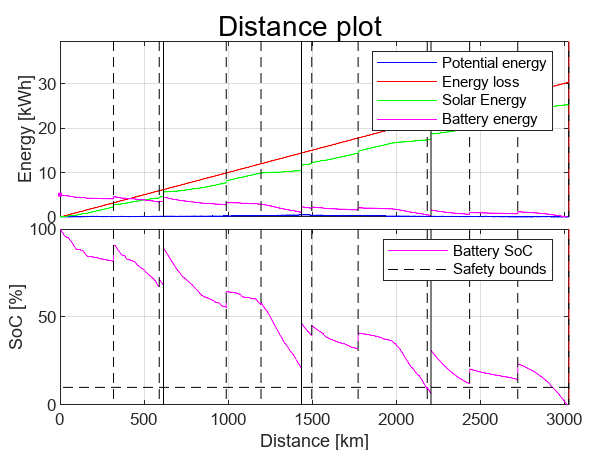

title = 'Distance plot';
synchronizeXAxes = true;
xaxisDist = distVec / 1000;
xlimVecDist = [0, driver.finishLocDist / 1000];
ylimVecDist = [0, max(J2kWh(ElossDist))];
builder = VerticalPlotBuilder(synchronizeXAxes, title);

builder.addPlot(xaxisDist, J2kWh(EpotDist),'-','Color','b');
builder.addPlot(xaxisDist, J2kWh(ElossDist),'-','Color',colour.loss);
builder.addPlot(xaxisDist, J2kWh(EcumSolar_driving),'-','Color',colour.solar);
builder.addPlot(xaxisDist, J2kWh(EBatDist),'-','Color',colour.battery);
builder.addPlot(0, J2kWh(Ebatmax),'.','Color',colour.battery);
builder.addLines('vertical', timeStopDist / 1000, 'k');
builder.addLines('vertical', driver.stopLocDist(2:end-1) / 1000, 'k--');
builder.addLines('vertical', driver.finishLocDist / 1000, 'r--');
builder.setYlabel("Energy [kWh]")
builder.setLegend("Potential energy","Energy loss","Solar Energy","Battery energy")
builder.setXlim(xlimVecDist)
builder.setYlim(ylimVecDist)

builder.startNewSubplot();
builder.addPlot(xaxisDist, SoCdist * 100,'-','Color',colour.battery);
builder.addLines('horizontal', (1 - EbatSafe / Ebatmax) * 100, 'k--');
builder.addLines('vertical', timeStopDist / 1000, 'k');
builder.addLines('vertical', driver.stopLocDist(2:end-1) / 1000, 'k--');
builder.addLines('vertical', driver.finishLocDist / 1000, 'r--');
builder.setYlabel("SoC [%]")
builder.setLegend("Battery SoC","Safety bounds")
builder.setXlim(xlimVecDist)
builder.setYlim([0, 100])

builder.setXlabel("Distance [km]");
builder.drawNow()

## Function

function [timeSec_driving, controlStopBeginSec, finishSec, horizon_driving] = timeVecCreatorForPlots(velocity, timeSec_8_17)
%with a given velocity we can cut the time plot corresponding to that specific stop location
    
persistent driver;
if isempty(driver)
    [~, ~, ~, driver] = loadData();
end % if

controlStopBeginSec = driver.stopLocDist(2:end-1) / velocity; %s ready to be plotted
finishSec = driver.stopLocDist(end) / velocity; %s
timeEndStops = controlStopBeginSec + seconds(minutes(30)); %s

horizon_spaceStop = false(size(timeSec_8_17));
for i = 1:driver.numSpaceStops
    %accounting for previous stops. Save only if between begin and end of
    %space stops
    tmp = (controlStopBeginSec(i) + (i-1)*seconds(minutes(30))) < timeSec_8_17 & timeSec_8_17 <= (timeEndStops(i) + (i-1)*seconds(minutes(30))); %DANGER WHEN EQUAL? ONE SHOULD BE =
    horizon_spaceStop = horizon_spaceStop | tmp; %update boolean vector
end % for

horizon_driving = ~horizon_spaceStop; %opposite, since nights stops already cut off
time_driving = timeSec_8_17(horizon_driving);

timeLen_driving = length(time_driving);
timeSec_driving = linspace(1, timeLen_driving, timeLen_driving)';
end % fct